% meta_struct_idx=12;
P_idx = 1;

raster_data = P(P_idx).raster(:,start_stim:stop_stim);
stimulus = P(P_idx).antennal_movement(:,start_stim:stop_stim);
% raster_data = downsample(raster_data,2);
% stimulus = downsample(stimulus,2);
% fs =10000;
stim_window = 0.02*fs; % 20 ms stimulus window
spike_window = fs*2e-3; % 2 ms (on either side of spike = 4 ms) %earlier 1 ms on either side
min_no_trials_required = (P(P_idx).complete_trials);

no_of_spikes =[];
min_isi = [];

for trial = 1:min_no_trials_required
    locs = find(raster_data(trial,:)==1);
    no_of_spikes(trial) = length(locs);
    min_isi(trial) = min(diff(locs/fs));
end

min_isi_all_trials = min(min_isi)

min_isi_all_trials = 0.0033

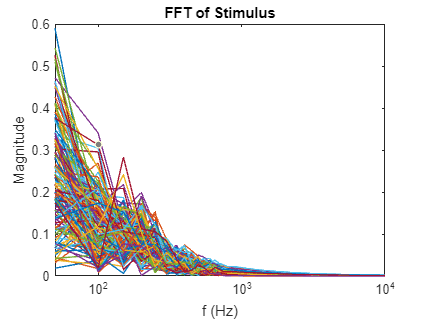


% std(no_of_spikes)
% var(no_of_spikes)
% std(no_of_spikes(1+no_of_trials/2:end))
% var(no_of_spikes(1+no_of_trials/2:end))

% raster = raster_data(1+no_of_trials/2:no_of_trials, :);
% stim = stimulus(1+no_of_trials/2:no_of_trials, :);
raster = raster_data;%(11:20,:);
stim = stimulus;%(11:20,:);
STA = P(P_idx).STA((end-stim_window):end);
ev1 = P(P_idx).ev1((end-stim_window):end);

[m,n] = size(raster);
% [row,col] = find(raster(1,:)==1);
locs_ref = find(raster(m,:)==1);
% locs_ref = unique(col);

% for trial = 2:m
ref = locs_ref(1);

% [~,locs_trials] = find(raster(:,ref-spike_window : ref+spike_window)==1);
% locs_trials = ref+locs_trials-11;
% jitter_sd = std(locs_trials);

jitter_sd = [];
max_stim_sd = [];
min_sd = [];
max_sd = [];
freq = [];
slope = [];
pos_amp = [];
stim_pattern_r = [];
time_to_prev_spike = [];
max_coeff_var = [];
fidelity = [];
stim_ev_r = [];

high_jitter_stim_patterns = [];
low_jitter_stim_patterns = [];
mid_jitter_stim_patterns = [];
mean_spiking_time = [];


for j = 1:length(locs_ref)
    
%     if locs_ref(j) > ref+spike_window
        ref = locs_ref(j);
        
        if ref>stim_window && (ref+spike_window)<length(stimulus)
            [spike_rows_trials, locs] = find(raster(:,ref-spike_window : ref+spike_window)==1);
            locs_trials = ref+locs-spike_window-1; % 11 to get the actual location from raster
            
           
            if length(locs_trials)<min_no_trials_required || std(locs_trials)==0
                continue;
            end
            
%             length(locs_trials)
            SD = (std(locs));
            jitter_sd = [jitter_sd; SD*1000/fs]; % * 1000 to convert to ms
            
%             if (SD*1000/fs) < 0.1
%                 disp(SD*1000/fs)
%                 disp(locs_trials)
%             end
            mean_spiking_time = [mean_spiking_time; mean(locs_trials)*1000/fs];
            
%             fidelity = [fidelity; 100*(length(spike_rows_trials)/P(P_idx).complete_trials)];
            
            prev_spike = [];
            
            for k=1:length(locs)
                prev_spike(k) = find(raster(spike_rows_trials(k), 1:locs_trials(k)-1), 1,"last");
            end
            isi = (locs_trials - prev_spike');
            time_to_prev_spike = [time_to_prev_spike; median(isi)];
            
            stim_patterns = stim(spike_rows_trials, (locs_trials-stim_window):locs_trials);
            [stim_freq, power_fft, frq_fft] = fft_stim_(mean(stim_patterns,1), fs);
            freq = [freq; stim_freq];
            
%             if SD<=0.2
%                 low_jitter_stim_patterns = [low_jitter_stim_patterns; stim_patterns];
%                 
%             elseif SD>0.2 && SD<=0.35
%                 mid_jitter_stim_patterns = [mid_jitter_stim_patterns; stim_patterns];
%                 
%             else
%                 high_jitter_stim_patterns = [high_jitter_stim_patterns; stim_patterns];
%             end
% 
%             STA = mean([low_jitter_stim_patterns; mid_jitter_stim_patterns; high_jitter_stim_patterns], 1);
            [max_pos, max_pos_ind] = max(stim_patterns,[], 2);
            [min_pos, min_pos_ind] = min(stim_patterns,[], 2);
%             amp = stim_patterns(max_pos_ind) - stim_patterns(min_pos_ind);
            amp = max_pos - min_pos;
            pattern_slope = amp*fs./(max_pos_ind - min_pos_ind);
            slope = [slope; mean(pattern_slope)];
            pos_amp = [pos_amp; mean(amp)];
            
            r = xcorr(STA, mean(stim_patterns,1), 'coeff');
            stim_pattern_r = [stim_pattern_r; max(r)];

%             r = corrcoef(STA, mean(stim_patterns,1));
%             stim_pattern_r = [stim_pattern_r; r(1,2)];
            
            ev_r = xcorr(ev1, mean(stim_patterns,1), 'coeff');
            stim_ev_r = [stim_ev_r; max(ev_r)];
            
            
            stim_patterns_sd = std(stim_patterns,0,1);
            stim_patterns_mean = mean(stim_patterns,1);
            stim_patterns_coeff_var = stim_patterns_sd./stim_patterns_mean;
            min_sd = [ min_sd; min(stim_patterns_sd)];
            max_sd = [max_sd; max(stim_patterns_sd)];
            max_stim_sd = [max_stim_sd; max(stim_patterns_sd)];
            max_coeff_var = [max_coeff_var; max(stim_patterns_coeff_var)];
            
            
        end
        
        
%     end
     
end

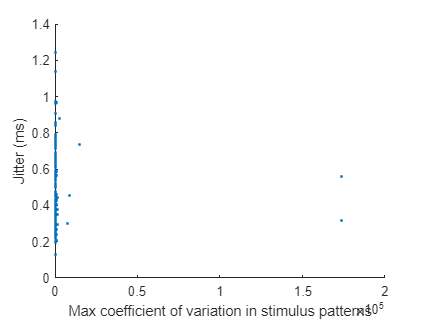


% S.LUT_intra_ID = LUT_intra_row_idx;
% S.jitter = jitter_sd;
% S.max_stim_sd = max_stim_sd;
% S.slope = slope;
% S.pos_amp = pos_amp;
% S.stim_pattern_r = stim_pattern_r;
% S.stim_ev_r = stim_ev_r;
% S.isi = ISI; %mean time to previous spike
% S.time_to_prev_spike_column = diff(mean_spiking_time);
% S.fs = fs;
% S.baseline_FR = mean(P(P_idx).avg_gcfr(1:(start_stim-1*fs)));
% S.mean_jitter = mean(jitter_sd);
% S.stim_pattern_freq = freq;
% 
% meta_struct(meta_struct_idx) = S;

% diff_sd = max_sd - min_sd;
figure;
scatter(max_coeff_var, jitter_sd,  '.');
xlabel('Max coefficient of variation in stimulus patterns');
ylabel('Jitter (ms)')

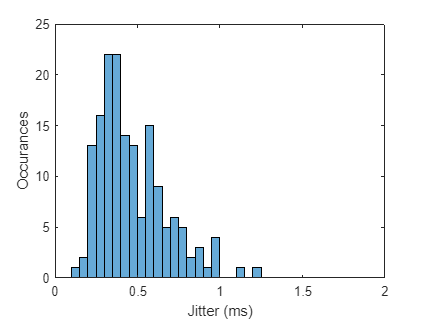

% ylim ([0 2]);
% title('58');

figure;
histogram(jitter_sd, 'BinWidth',1000/fs);
xlabel('Jitter (ms)');
ylabel('Occurances')
xlim([0 2]);

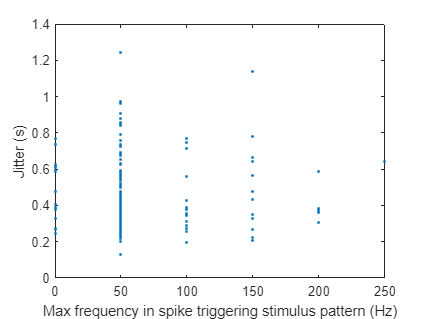


figure;
plot(freq, jitter_sd, '.');
xlabel('Max frequency in spike triggering stimulus pattern (Hz)');
ylabel('Jitter (s)');

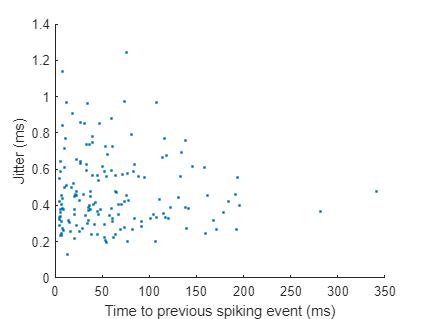


figure;
scatter(diff(mean_spiking_time), jitter_sd(2:end), '.');
ylabel('Jitter (ms)');
xlabel('Time to previous spiking event (ms)');

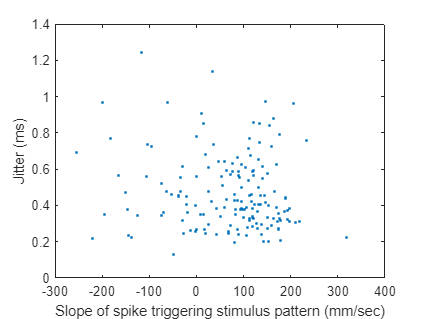


figure;
plot(slope, jitter_sd, '.');
xlabel('Slope of spike triggering stimulus pattern (mm/sec)');
ylabel('Jitter (ms)');

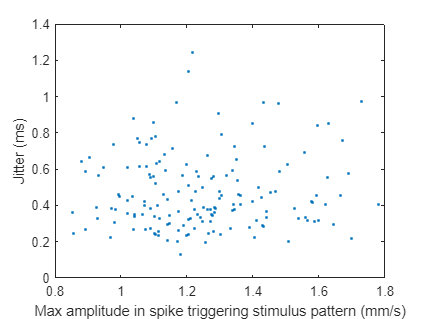

% ylim([0 2]);

figure;
plot(pos_amp, jitter_sd,  '.');
xlabel('Max amplitude in spike triggering stimulus pattern (mm/s)');
ylabel('Jitter (ms)');

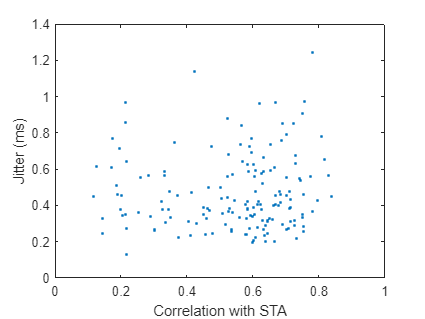

% ylim([0 2]);

figure;
plot(stim_pattern_r, jitter_sd, '.');
xlabel('Correlation with STA');
ylabel('Jitter (ms)');

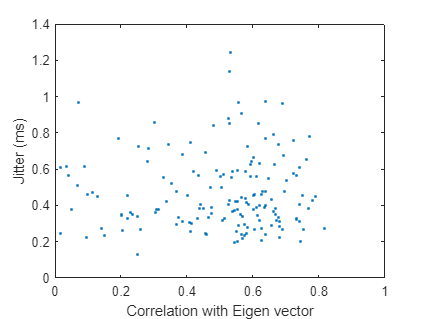

% ylim([0 2]);

figure;
plot(stim_ev_r, jitter_sd, '.');
xlabel('Correlation with Eigen vector');
ylabel('Jitter (ms)');

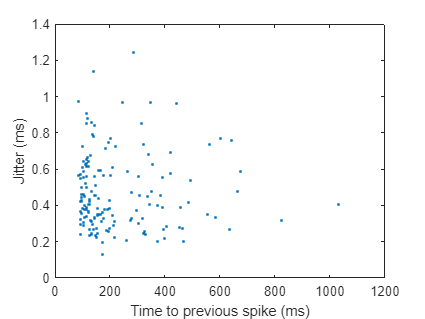

% ylim ([0 2]);


% figure;
% scatter3(jitter_sd,time_to_prev_spike,stim_pattern_r);
% ylabel('Time to previous spike (ms)');
% xlabel('Jitter (ms)');
% zlabel('Correlation with STA');

figure;
plot(time_to_prev_spike, jitter_sd, '.');
xlabel('Time to previous spike (ms)');
ylabel('Jitter (ms)');

% ylim([0 2]);

% figure; 
% plot(mean(low_jitter_stim_patterns,1)); hold on;
% plot(mean(mid_jitter_stim_patterns,1));
% plot(mean(high_jitter_stim_patterns,1));
% plot(STA);
% legend("low jitter", "mid jitter", "high jitter", "STA", "Location","best");
% 
% t = linspace(10,0,length(stim_patterns));
% figure;
% stdshade((low_jitter_stim_patterns),0.1,'b',t); hold on;
% % stdshade((mid_jitter_stim_patterns),0.1,'r',t);
% stdshade((high_jitter_stim_patterns),0.1,'y',t);
% % legend("low jitter", "mid jitter", "high jitter");

% S = struct();



figure;
scatter(fidelity, max_coeff_var, '.');
ylabel('Max coefficient of variation in stimulus patterns (m)');
xlabel('Fidelity (%)');
% title('58');

figure;
histogram(fidelity,100);
xlabel('Fidelity (%)');
ylabel('Occurances')
% figure;
% plot(freq, jitter_sd, '.');
% xlabel('Max frequency in spike triggering stimulus pattern (Hz)');
% ylabel('Jitter (s)');

figure;
plot(fidelity, slope, '.');
ylabel('Max amplitude in spike triggering stimulus pattern (mm)');
xlabel('Fidelity (%)');

figure;
plot(fidelity, pos_amp, '.');
ylabel('Slope of spike triggering stimulus pattern (mm/sec)');
xlabel('Fidelity (%)');

figure;
plot(fidelity, stim_pattern_r, '.');
ylabel('Correlation with STA');
xlabel('Fidelity (%)');

figure;
plot(fidelity, time_to_prev_spike, '.');
ylabel('Time to previous spike (ms)');
xlabel('Fidelity (%)');


% T = [T; Tnew];
